# Visualizing Sensors Data

Authors: Ana Siesto Pérez and Xavier Marti Llull

Team: G11-A

Shared Link with the teacher: [https://drive.matlab.com/sharing/d7b554c7-ab4c-48e1-85a1-85981395d743](https://drive.matlab.com/sharing/d7b554c7-ab4c-48e1-85a1-85981395d743) 

## **Load data**

clear
close all
load("Sensors_Data.mat");

Tf = 60.08;
Ts = 0.02;
W = 0.52;
Gear_ratio = 100;
r = 0.1;

R_inc = right_angular_speed(:, 2) / Gear_ratio * r * Ts;
L_inc = left_angular_speed(:, 2) / Gear_ratio * r * Ts;
t = (0:Ts:Tf-Ts)';

## Odometry

delta_d = (R_inc+L_inc)/2;
delta_t = (R_inc-L_inc)/W;

## Pose integration

Initial_pose=transl(0,0,0)

Initial_pose =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Initial_position=transl(Initial_pose)

Initial_position =      0
     0
     0


Initial_orientation=0

Initial_orientation = 0

x(1)=Initial_position(1)

x = 0

y(1)=Initial_position(2)

y = 0

o(1)=Initial_orientation

o = 0

for i=1:(length(t)-1)
    x(i+1)= x(i)+delta_d(i)*cos(o(i));
    y(i+1)= y(i)+delta_d(i)*sin(o(i));
    o(i+1)=o(i)+delta_t(i);
end

## Mapping

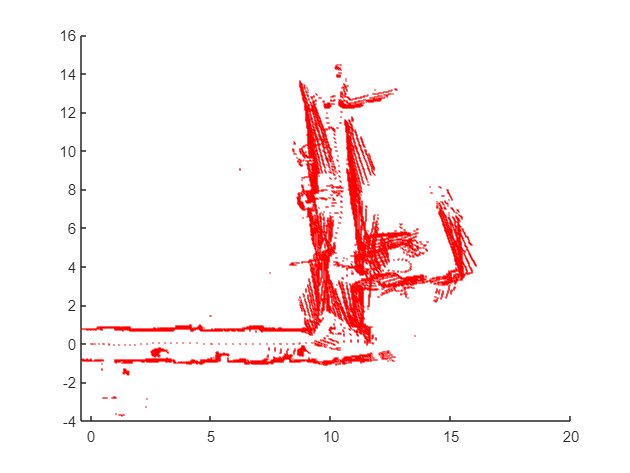

count = 1;
m = size(polar_laser_data);
for i=1:m(1)
    for j=1:(m(2)-1)
        if polar_laser_data(i, j)/1000 > 0
            alpha = (j-1) * 0.3515 * pi/180;
            if alpha <= 240/2
                alpha = o(20*i) + alpha - 122*pi/180;
            else
                alpha = o(20*i) - alpha - 122*pi/180;
            end
            x2(count) = x(20*i) + polar_laser_data(i, j)/1000 * cos(alpha);
            y2(count) = y(20*i) + polar_laser_data(i, j)/1000 * sin(alpha);
            count = count + 1;
        end
    end
end

figure
scatter(x2, y2, 0.5, '.','red')